# Inverted double pendulum with Lagrangian method

# 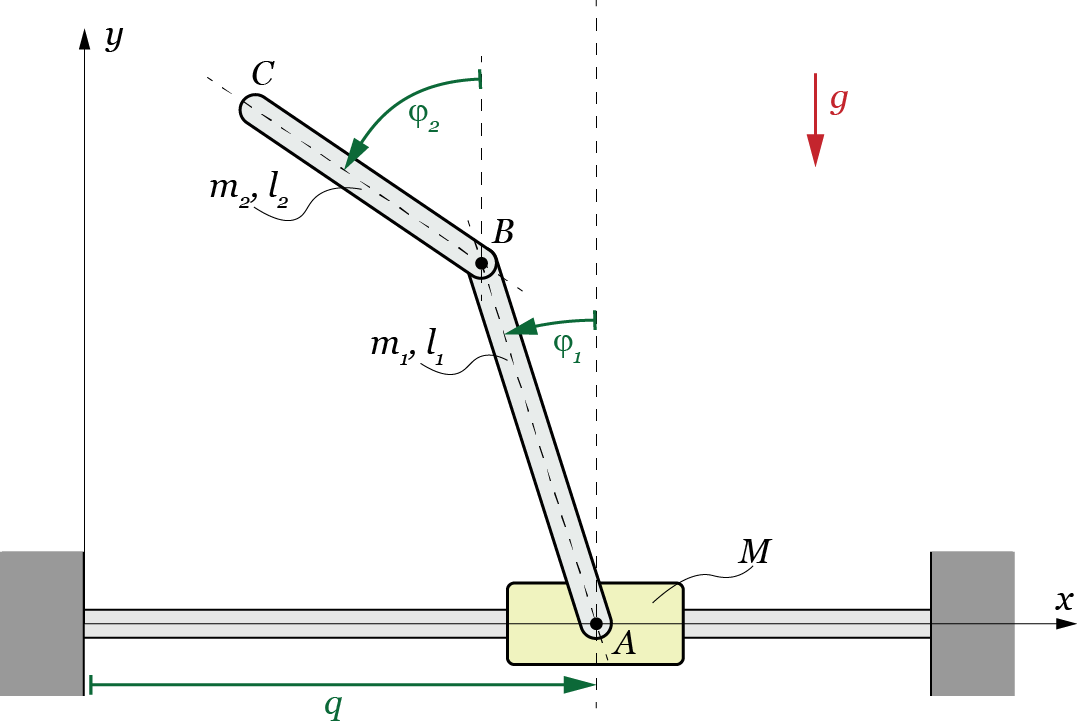

## Define the reference frame variables and the relationships between them

clear; clc;
% Declare symbolic variables:
syms t q(t) f1(t) f2(t) l1 l2 M m1 m2 g

% For the following values, we specify that their value cannot be 0.
assume(l1 ~= 0);
assume(l2 ~= 0);
assume(M ~= 0);
assume(m1 ~= 0);
assume(m2 ~= 0);
assume(g ~= 0);

### Homogenius transformation matrices:

% Homogenius transformation matrices
T0c = [1 0 0 q
       0 1 0 0
       0 0 1 0
       0 0 0 1];

Tc1 = [-sin(f1) -cos(f1) 0 0
       cos(f1) -sin(f1) 0 0
       0 0 1 0
       0 0 0 1];

T12 = [cos(f2-f1) -sin(f2-f1) 0 l1
       sin(f2-f1) cos(f2-f1) 0 0
       0 0 1 0
       0 0 0 1];

### Point coordinates:

% Point coordinates:
%   Local
rcA  = [0; 0; 0; 1];
r1S1 = [l1/2; 0; 0; 1];
r1B =  [l1; 0; 0; 1];
r2S2 = [l2/2; 0; 0; 1];
r2C =  [l2; 0; 0; 1];

%   Global
rA = T0c * rcA;
rS1 = T0c * Tc1 * r1S1;
rB = T0c * Tc1 * r1B;
rS2 = simplify(T0c * Tc1 * T12 * r2S2);
rC = simplify(T0c * Tc1 * T12 * r2C);

rA

$$rA(t) = \left(\begin{array}{c} q\left(t\right)\\ 0\\ 0\\ 1 \end{array}\right)$$

rS1

$$rS1(t) = \left(\begin{array}{c} q\left(t\right)-\frac{l_{1}\,\sin\left(f_{1}\left(t\right)\right)}{2}\\ \frac{l_{1}\,\cos\left(f_{1}\left(t\right)\right)}{2}\\ 0\\ 1 \end{array}\right)$$

rS2

$$rS2(t) = \left(\begin{array}{c} q\left(t\right)-l_{1}\,\sin\left(f_{1}\left(t\right)\right)-\frac{l_{2}\,\sin\left(f_{2}\left(t\right)\right)}{2}\\ l_{1}\,\cos\left(f_{1}\left(t\right)\right)+\frac{l_{2}\,\cos\left(f_{2}\left(t\right)\right)}{2}\\ 0\\ 1 \end{array}\right)$$

### Omega angular velocities

% Omega angular velocities
om1 = [0; 0; diff(f1,t)]

$$om1(t) = \left(\begin{array}{c} 0\\ 0\\ \frac{\partial }{\partial t}f_{1}\left(t\right) \end{array}\right)$$

om2 = [0; 0; diff(f2,t)]

$$om2(t) = \left(\begin{array}{c} 0\\ 0\\ \frac{\partial }{\partial t}f_{2}\left(t\right) \end{array}\right)$$

### Moment of inertias

% Moment of inertias
syms I_S1 I_S2

%I_S1=m1*l1*l1/12
%I_S2=m2*l2*l2/12

### Auxiliary variables

% Auxiliary variables
rA_t=rA(t)

$$rA\_t = \left(\begin{array}{c} q\left(t\right)\\ 0\\ 0\\ 1 \end{array}\right)$$

rA_=rA_t(1:3);
rAd=diff(rA_,t)

$$rAd = \left(\begin{array}{c} \frac{\partial }{\partial t}q\left(t\right)\\ 0\\ 0 \end{array}\right)$$

rAd_pow=transpose(rAd)*rAd;

rS1_t=rS1(t)

$$rS1\_t = \left(\begin{array}{c} q\left(t\right)-\frac{l_{1}\,\sin\left(f_{1}\left(t\right)\right)}{2}\\ \frac{l_{1}\,\cos\left(f_{1}\left(t\right)\right)}{2}\\ 0\\ 1 \end{array}\right)$$

rS1_=rS1_t(1:3);
rS1d=diff(rS1_,t)

$$rS1d = \left(\begin{array}{c} \frac{\partial }{\partial t}q\left(t\right)-\frac{l_{1}\,\cos\left(f_{1}\left(t\right)\right)\,\frac{\partial }{\partial t}f_{1}\left(t\right)}{2}\\ -\frac{l_{1}\,\sin\left(f_{1}\left(t\right)\right)\,\frac{\partial }{\partial t}f_{1}\left(t\right)}{2}\\ 0 \end{array}\right)$$

rS1d_pow=transpose(rS1d)*rS1d;

rS2_t=rS2(t)

$$rS2\_t = \left(\begin{array}{c} q\left(t\right)-l_{1}\,\sin\left(f_{1}\left(t\right)\right)-\frac{l_{2}\,\sin\left(f_{2}\left(t\right)\right)}{2}\\ l_{1}\,\cos\left(f_{1}\left(t\right)\right)+\frac{l_{2}\,\cos\left(f_{2}\left(t\right)\right)}{2}\\ 0\\ 1 \end{array}\right)$$

rS2_=rS2_t(1:3);
rS2d=diff(rS2_,t)

$$rS2d = \left(\begin{array}{c} \frac{\partial }{\partial t}q\left(t\right)-l_{1}\,\cos\left(f_{1}\left(t\right)\right)\,\frac{\partial }{\partial t}f_{1}\left(t\right)-\frac{l_{2}\,\cos\left(f_{2}\left(t\right)\right)\,\frac{\partial }{\partial t}f_{2}\left(t\right)}{2}\\ -l_{1}\,\sin\left(f_{1}\left(t\right)\right)\,\frac{\partial }{\partial t}f_{1}\left(t\right)-\frac{l_{2}\,\sin\left(f_{2}\left(t\right)\right)\,\frac{\partial }{\partial t}f_{2}\left(t\right)}{2}\\ 0 \end{array}\right)$$

rS2d_pow=transpose(rS2d)*rS2d;

om1_pow = transpose(om1)*om1

$$om1\_pow(t) = {\left(\frac{\partial }{\partial t}f_{1}\left(t\right)\right)}^{2}$$

om2_pow = transpose(om2)*om2

$$om2\_pow(t) = {\left(\frac{\partial }{\partial t}f_{2}\left(t\right)\right)}^{2}$$

## Writing down the equation of motion

This will be done using the Lagrange method.


$$\frac{d}{dt}\left(\frac{\partial L}{\partial \dot{\theta}}\right) - \frac{\partial L}{\partial \theta} = q
$$


### Energy equations:

#### Kinetic energy

% Kinetic energy
E0_kin=1/2*M*rAd_pow

$$E0\_kin = \frac{M\,{\left(\frac{\partial }{\partial t}q\left(t\right)\right)}^{2}}{2}$$

E1_kin=1/2*m1*rS1d_pow + 1/2*I_S1*om1_pow

$$E1\_kin(t) = \frac{m_{1}\,\left({\left(\frac{\partial }{\partial t}q\left(t\right)-\frac{l_{1}\,\cos\left(f_{1}\left(t\right)\right)\,\frac{\partial }{\partial t}f_{1}\left(t\right)}{2}\right)}^{2}+\frac{{l_{1}}^{2}\,{\sin\left(f_{1}\left(t\right)\right)}^{2}\,{\left(\frac{\partial }{\partial t}f_{1}\left(t\right)\right)}^{2}}{4}\right)}{2}+\frac{I_{\mathrm{S1}}\,{\left(\frac{\partial }{\partial t}f_{1}\left(t\right)\right)}^{2}}{2}$$

E2_kin=1/2*m2*rS2d_pow + 1/2*I_S2*om2_pow

$$E2\_kin(t) = \frac{I_{\mathrm{S2}}\,{\left(\frac{\partial }{\partial t}f_{2}\left(t\right)\right)}^{2}}{2}+\frac{m_{2}\,\left({\left(-\frac{\partial }{\partial t}q\left(t\right)+l_{1}\,\cos\left(f_{1}\left(t\right)\right)\,\frac{\partial }{\partial t}f_{1}\left(t\right)+\frac{l_{2}\,\cos\left(f_{2}\left(t\right)\right)\,\frac{\partial }{\partial t}f_{2}\left(t\right)}{2}\right)}^{2}+{\left(l_{1}\,\sin\left(f_{1}\left(t\right)\right)\,\frac{\partial }{\partial t}f_{1}\left(t\right)+\frac{l_{2}\,\sin\left(f_{2}\left(t\right)\right)\,\frac{\partial }{\partial t}f_{2}\left(t\right)}{2}\right)}^{2}\right)}{2}$$

% Total kinetic energy
T=E0_kin+E1_kin+E2_kin;
collect(T,[diff(q) diff(f1) diff(f2)])

$$ans(t) = \begin{array}{l} \left(\frac{M}{2}+\frac{m_{1}}{2}+\frac{m_{2}}{2}\right)\,{\left(\frac{\partial }{\partial t}q\left(t\right)\right)}^{2}+\left(-\frac{l_{1}\,m_{1}\,\cos\left(f_{1}\left(t\right)\right)}{2}-l_{1}\,m_{2}\,\cos\left(f_{1}\left(t\right)\right)\right)\,\frac{\partial }{\partial t}q\left(t\right)\,\frac{\partial }{\partial t}f_{1}\left(t\right)+\left(-\frac{l_{2}\,m_{2}\,\cos\left(f_{2}\left(t\right)\right)}{2}\right)\,\frac{\partial }{\partial t}q\left(t\right)\,\frac{\partial }{\partial t}f_{2}\left(t\right)+\left(\frac{I_{\mathrm{S1}}}{2}+\frac{m_{2}\,\left(\sigma_{2}+\sigma_{1}\right)}{2}+\frac{m_{1}\,\left(\frac{\sigma_{2}}{4}+\frac{\sigma_{1}}{4}\right)}{2}\right)\,{\left(\frac{\partial }{\partial t}f_{1}\left(t\right)\right)}^{2}+\frac{m_{2}\,\left(l_{1}\,l_{2}\,\cos\left(f_{1}\left(t\right)\right)\,\cos\left(f_{2}\left(t\right)\right)+l_{1}\,l_{2}\,\sin\left(f_{1}\left(t\right)\right)\,\sin\left(f_{2}\left(t\right)\right)\right)}{2}\,\frac{\partial }{\partial t}f_{1}\left(t\right)\,\frac{\partial }{\partial t}f_{2}\left(t\right)+\left(\frac{I_{\mathrm{S2}}}{2}+\frac{m_{2}\,\left(\frac{{l_{2}}^{2}\,{\cos\left(f_{2}\left(t\right)\right)}^{2}}{4}+\frac{{l_{2}}^{2}\,{\sin\left(f_{2}\left(t\right)\right)}^{2}}{4}\right)}{2}\right)\,{\left(\frac{\partial }{\partial t}f_{2}\left(t\right)\right)}^{2}\\ \mathrm{where}\\ \sigma_{1}={l_{1}}^{2}\,{\sin\left(f_{1}\left(t\right)\right)}^{2}\\ \sigma_{2}={l_{1}}^{2}\,{\cos\left(f_{1}\left(t\right)\right)}^{2} \end{array}$$

#### Potential energy

E0_pot=0

E0_pot = 0

E1_pot=m1*g*rS1_(2)

$$E1\_pot = \frac{g\,l_{1}\,m_{1}\,\cos\left(f_{1}\left(t\right)\right)}{2}$$

E2_pot=m2*g*rS2_(2)

$$E2\_pot = g\,m_{2}\,\left(l_{1}\,\cos\left(f_{1}\left(t\right)\right)+\frac{l_{2}\,\cos\left(f_{2}\left(t\right)\right)}{2}\right)$$


% Total potential energy
U=E0_pot+E1_pot+E2_pot;

### Lagrange function

% Lagrange function
L=simplify(collect(simplify(collect(T-U,[g diff(q) diff(f1) diff(f2)])),[diff(q)*diff(f1) diff(f1)*diff(f2) diff(f2)*diff(q) diff(q)^2 diff(f1)^2 diff(f2)^2 g]))

$$L(t) = \left(\frac{m_{2}\,{l_{2}}^{2}}{8}+\frac{I_{\mathrm{S2}}}{2}\right)\,{\left(\frac{\partial }{\partial t}f_{2}\left(t\right)\right)}^{2}+{\left(\frac{\partial }{\partial t}q\left(t\right)\right)}^{2}\,\left(\frac{M}{2}+\frac{m_{1}}{2}+\frac{m_{2}}{2}\right)-g\,\left(\frac{l_{1}\,m_{1}\,\cos\left(f_{1}\left(t\right)\right)}{2}+l_{1}\,m_{2}\,\cos\left(f_{1}\left(t\right)\right)+\frac{l_{2}\,m_{2}\,\cos\left(f_{2}\left(t\right)\right)}{2}\right)+{\left(\frac{\partial }{\partial t}f_{1}\left(t\right)\right)}^{2}\,\left(\frac{I_{\mathrm{S1}}}{2}+\frac{{l_{1}}^{2}\,m_{1}}{8}+\frac{{l_{1}}^{2}\,m_{2}}{2}\right)-\frac{l_{1}\,\cos\left(f_{1}\left(t\right)\right)\,\left(m_{1}+2\,m_{2}\right)\,\frac{\partial }{\partial t}q\left(t\right)\,\frac{\partial }{\partial t}f_{1}\left(t\right)}{2}-\frac{l_{2}\,m_{2}\,\cos\left(f_{2}\left(t\right)\right)\,\frac{\partial }{\partial t}q\left(t\right)\,\frac{\partial }{\partial t}f_{2}\left(t\right)}{2}+\frac{l_{1}\,l_{2}\,m_{2}\,\cos\left(f_{1}\left(t\right)-f_{2}\left(t\right)\right)\,\frac{\partial }{\partial t}f_{2}\left(t\right)\,\frac{\partial }{\partial t}f_{1}\left(t\right)}{2}$$

Substitute variables in place of the derivation to make it more transparent.

syms dq_e(t) df1_e(t) df2_e(t)

L = subs(L, [diff(q) diff(f1) diff(f2)], [dq_e df1_e df2_e])

$$L(t) = \left(\frac{I_{\mathrm{S1}}}{2}+\frac{{l_{1}}^{2}\,m_{1}}{8}+\frac{{l_{1}}^{2}\,m_{2}}{2}\right)\,{{\mathrm{df}}_{1,e}\left(t\right)}^{2}+\frac{l_{1}\,l_{2}\,m_{2}\,\cos\left(f_{1}\left(t\right)-f_{2}\left(t\right)\right)\,{\mathrm{df}}_{1,e}\left(t\right)\,{\mathrm{df}}_{2,e}\left(t\right)}{2}-\frac{l_{1}\,\cos\left(f_{1}\left(t\right)\right)\,\left(m_{1}+2\,m_{2}\right)\,{\mathrm{df}}_{1,e}\left(t\right)\,{\mathrm{dq}}_{e}\left(t\right)}{2}+\left(\frac{m_{2}\,{l_{2}}^{2}}{8}+\frac{I_{\mathrm{S2}}}{2}\right)\,{{\mathrm{df}}_{2,e}\left(t\right)}^{2}-\frac{l_{2}\,m_{2}\,\cos\left(f_{2}\left(t\right)\right)\,{\mathrm{df}}_{2,e}\left(t\right)\,{\mathrm{dq}}_{e}\left(t\right)}{2}+\left(\frac{M}{2}+\frac{m_{1}}{2}+\frac{m_{2}}{2}\right)\,{{\mathrm{dq}}_{e}\left(t\right)}^{2}-g\,\left(\frac{l_{1}\,m_{1}\,\cos\left(f_{1}\left(t\right)\right)}{2}+l_{1}\,m_{2}\,\cos\left(f_{1}\left(t\right)\right)+\frac{l_{2}\,m_{2}\,\cos\left(f_{2}\left(t\right)\right)}{2}\right)$$

L_collect = collect(L,[dq_e^2 dq_e df1_e^2 df2_e^2 g])

$$L\_collect(t) = \left(\frac{M}{2}+\frac{m_{1}}{2}+\frac{m_{2}}{2}\right)\,{{\mathrm{dq}}_{e}\left(t\right)}^{2}+\left(-\frac{l_{2}\,m_{2}\,\cos\left(f_{2}\left(t\right)\right)\,{\mathrm{df}}_{2,e}\left(t\right)}{2}-\frac{l_{1}\,\cos\left(f_{1}\left(t\right)\right)\,{\mathrm{df}}_{1,e}\left(t\right)\,\left(m_{1}+2\,m_{2}\right)}{2}\right)\,{\mathrm{dq}}_{e}\left(t\right)+\left(\frac{I_{\mathrm{S1}}}{2}+\frac{{l_{1}}^{2}\,m_{1}}{8}+\frac{{l_{1}}^{2}\,m_{2}}{2}\right)\,{{\mathrm{df}}_{1,e}\left(t\right)}^{2}+\left(\frac{m_{2}\,{l_{2}}^{2}}{8}+\frac{I_{\mathrm{S2}}}{2}\right)\,{{\mathrm{df}}_{2,e}\left(t\right)}^{2}+\left(-\frac{l_{1}\,m_{1}\,\cos\left(f_{1}\left(t\right)\right)}{2}-l_{1}\,m_{2}\,\cos\left(f_{1}\left(t\right)\right)-\frac{l_{2}\,m_{2}\,\cos\left(f_{2}\left(t\right)\right)}{2}\right)\,g+\frac{l_{1}\,l_{2}\,m_{2}\,\cos\left(f_{1}\left(t\right)-f_{2}\left(t\right)\right)\,{\mathrm{df}}_{1,e}\left(t\right)\,{\mathrm{df}}_{2,e}\left(t\right)}{2}$$

## Solving the equation of motion

syms dpt(t)

### Solution to the first degree of freedom

%q:
dL_dq = subs(functionalDerivative(L, q),[dq_e df1_e df2_e],[diff(q) diff(f1) diff(f2)]);
dL_dqdot = subs(functionalDerivative(L,dq_e),[dq_e df1_e df2_e],[diff(q) diff(f1) diff(f2)]);
d_dL_dqdot_dt = diff(dL_dqdot, t);

dL_dq = collect(dL_dq, [diff(diff(q)) diff(diff(f1)) diff(diff(f2)) diff(q) diff(f1) diff(f2) q f1 f2])

$$dL\_dq(t) = 0$$

dL_dqdot = collect(dL_dqdot, [diff(diff(q)) diff(diff(f1)) diff(diff(f2)) diff(q) diff(f1) diff(f2) q f1 f2])

$$dL\_dqdot(t) = \left(M+m_{1}+m_{2}\right)\,\frac{\partial }{\partial t}q\left(t\right)+\left(-\frac{l_{1}\,m_{1}\,\cos\left(f_{1}\left(t\right)\right)}{2}-l_{1}\,m_{2}\,\cos\left(f_{1}\left(t\right)\right)\right)\,\frac{\partial }{\partial t}f_{1}\left(t\right)+\left(-\frac{l_{2}\,m_{2}\,\cos\left(f_{2}\left(t\right)\right)}{2}\right)\,\frac{\partial }{\partial t}f_{2}\left(t\right)$$

d_dL_dqdot_dt = collect(d_dL_dqdot_dt, [diff(diff(q)) diff(diff(f1)) diff(diff(f2)) diff(q) diff(f1) diff(f2) q f1 f2])

$$d\_dL\_dqdot\_dt(t) = \left(M+m_{1}+m_{2}\right)\,\frac{\partial^{2}}{\partial t^{2}}q\left(t\right)+\left(-\frac{l_{1}\,m_{1}\,\cos\left(f_{1}\left(t\right)\right)}{2}-l_{1}\,m_{2}\,\cos\left(f_{1}\left(t\right)\right)\right)\,\frac{\partial^{2}}{\partial t^{2}}f_{1}\left(t\right)+\left(-\frac{l_{2}\,m_{2}\,\cos\left(f_{2}\left(t\right)\right)}{2}\right)\,\frac{\partial^{2}}{\partial t^{2}}f_{2}\left(t\right)+\left(\frac{l_{1}\,m_{1}\,\sin\left(f_{1}\left(t\right)\right)}{2}+l_{1}\,m_{2}\,\sin\left(f_{1}\left(t\right)\right)\right)\,{\left(\frac{\partial }{\partial t}f_{1}\left(t\right)\right)}^{2}+\frac{l_{2}\,m_{2}\,\sin\left(f_{2}\left(t\right)\right)}{2}\,{\left(\frac{\partial }{\partial t}f_{2}\left(t\right)\right)}^{2}$$

Equation to the first degree of freedom:

qLp= simplify(d_dL_dqdot_dt - dL_dq)

$$qLp(t) = \left(M+m_{1}+m_{2}\right)\,\frac{\partial^{2}}{\partial t^{2}}q\left(t\right)+\frac{l_{2}\,m_{2}\,\sin\left(f_{2}\left(t\right)\right)\,{\left(\frac{\partial }{\partial t}f_{2}\left(t\right)\right)}^{2}}{2}-\frac{l_{2}\,m_{2}\,\cos\left(f_{2}\left(t\right)\right)\,\frac{\partial^{2}}{\partial t^{2}}f_{2}\left(t\right)}{2}+\frac{l_{1}\,\sin\left(f_{1}\left(t\right)\right)\,\left(m_{1}+2\,m_{2}\right)\,{\left(\frac{\partial }{\partial t}f_{1}\left(t\right)\right)}^{2}}{2}-\frac{l_{1}\,\cos\left(f_{1}\left(t\right)\right)\,\left(m_{1}+2\,m_{2}\right)\,\frac{\partial^{2}}{\partial t^{2}}f_{1}\left(t\right)}{2}$$

### Solution to the second degree of freedom

%f1:
dL_df1 = subs(functionalDerivative(L, f1),[dq_e df1_e df2_e],[diff(q) diff(f1) diff(f2)]);
dL_df1dot = subs(functionalDerivative(L,df1_e),[dq_e df1_e df2_e],[diff(q) diff(f1) diff(f2)]);
d_dL_df1dot_dt = diff(dL_df1dot, t);

dL_df1 = collect(dL_df1, [diff(diff(q)) diff(diff(f1)) diff(diff(f2)) diff(q) diff(f1) diff(f2) q f1 f2])

$$dL\_df1(t) = \left(\frac{l_{1}\,m_{1}\,\sin\left(f_{1}\left(t\right)\right)}{2}+l_{1}\,m_{2}\,\sin\left(f_{1}\left(t\right)\right)\right)\,\frac{\partial }{\partial t}q\left(t\right)\,\frac{\partial }{\partial t}f_{1}\left(t\right)+\left(-\frac{l_{1}\,l_{2}\,m_{2}\,\sin\left(f_{1}\left(t\right)-f_{2}\left(t\right)\right)}{2}\right)\,\frac{\partial }{\partial t}f_{1}\left(t\right)\,\frac{\partial }{\partial t}f_{2}\left(t\right)+\frac{g\,l_{1}\,m_{1}\,\sin\left(f_{1}\left(t\right)\right)}{2}+g\,l_{1}\,m_{2}\,\sin\left(f_{1}\left(t\right)\right)$$

dL_df1dot = collect(dL_df1dot, [diff(diff(q)) diff(diff(f1)) diff(diff(f2)) diff(q) diff(f1) diff(f2) q f1 f2])

$$dL\_df1dot(t) = \left(-\frac{l_{1}\,m_{1}\,\cos\left(f_{1}\left(t\right)\right)}{2}-l_{1}\,m_{2}\,\cos\left(f_{1}\left(t\right)\right)\right)\,\frac{\partial }{\partial t}q\left(t\right)+\left(I_{\mathrm{S1}}+\frac{{l_{1}}^{2}\,m_{1}}{4}+{l_{1}}^{2}\,m_{2}\right)\,\frac{\partial }{\partial t}f_{1}\left(t\right)+\frac{l_{1}\,l_{2}\,m_{2}\,\cos\left(f_{1}\left(t\right)-f_{2}\left(t\right)\right)}{2}\,\frac{\partial }{\partial t}f_{2}\left(t\right)$$

d_dL_df1dot_dt = collect(d_dL_df1dot_dt, [diff(diff(q)) diff(diff(f1)) diff(diff(f2)) diff(q) diff(f1) diff(f2) q f1 f2])

$$d\_dL\_df1dot\_dt(t) = \begin{array}{l} \left(-\frac{l_{1}\,m_{1}\,\cos\left(f_{1}\left(t\right)\right)}{2}-l_{1}\,m_{2}\,\cos\left(f_{1}\left(t\right)\right)\right)\,\frac{\partial^{2}}{\partial t^{2}}q\left(t\right)+\left(I_{\mathrm{S1}}+\frac{{l_{1}}^{2}\,m_{1}}{4}+{l_{1}}^{2}\,m_{2}\right)\,\frac{\partial^{2}}{\partial t^{2}}f_{1}\left(t\right)+\frac{l_{1}\,l_{2}\,m_{2}\,\cos\left(\sigma_{2}\right)}{2}\,\frac{\partial^{2}}{\partial t^{2}}f_{2}\left(t\right)+\left(\frac{l_{1}\,m_{1}\,\sin\left(f_{1}\left(t\right)\right)}{2}+l_{1}\,m_{2}\,\sin\left(f_{1}\left(t\right)\right)\right)\,\frac{\partial }{\partial t}q\left(t\right)\,\frac{\partial }{\partial t}f_{1}\left(t\right)+\left(-\sigma_{1}\right)\,\frac{\partial }{\partial t}f_{1}\left(t\right)\,\frac{\partial }{\partial t}f_{2}\left(t\right)+\sigma_{1}\,{\left(\frac{\partial }{\partial t}f_{2}\left(t\right)\right)}^{2}\\ \mathrm{where}\\ \sigma_{1}=\frac{l_{1}\,l_{2}\,m_{2}\,\sin\left(\sigma_{2}\right)}{2}\\ \sigma_{2}=f_{1}\left(t\right)-f_{2}\left(t\right) \end{array}$$

Equation to the second degree of freedom:

f1Lp= simplify(d_dL_df1dot_dt - dL_df1)

$$f1Lp(t) = \begin{array}{l} \left(I_{\mathrm{S1}}+\frac{{l_{1}}^{2}\,m_{1}}{4}+{l_{1}}^{2}\,m_{2}\right)\,\frac{\partial^{2}}{\partial t^{2}}f_{1}\left(t\right)-\frac{l_{1}\,\cos\left(f_{1}\left(t\right)\right)\,\left(m_{1}+2\,m_{2}\right)\,\frac{\partial^{2}}{\partial t^{2}}q\left(t\right)}{2}-\frac{g\,l_{1}\,m_{1}\,\sin\left(f_{1}\left(t\right)\right)}{2}-g\,l_{1}\,m_{2}\,\sin\left(f_{1}\left(t\right)\right)+\frac{l_{1}\,l_{2}\,m_{2}\,\sin\left(\sigma_{1}\right)\,{\left(\frac{\partial }{\partial t}f_{2}\left(t\right)\right)}^{2}}{2}+\frac{l_{1}\,l_{2}\,m_{2}\,\cos\left(\sigma_{1}\right)\,\frac{\partial^{2}}{\partial t^{2}}f_{2}\left(t\right)}{2}\\ \mathrm{where}\\ \sigma_{1}=f_{1}\left(t\right)-f_{2}\left(t\right) \end{array}$$

### Solution to the third degree of freedom

%f2:
dL_df2 = subs(functionalDerivative(L, f2),[dq_e df1_e df2_e],[diff(q) diff(f1) diff(f2)]);
dL_df2dot = subs(functionalDerivative(L,df2_e),[dq_e df1_e df2_e],[diff(q) diff(f1) diff(f2)]);
d_dL_df2dot_dt = diff(dL_df2dot, t);

dL_df2 = collect(dL_df2, [diff(diff(q)) diff(diff(f1)) diff(diff(f2)) diff(q) diff(f1) diff(f2) q f1 f2])

$$dL\_df2(t) = \frac{l_{2}\,m_{2}\,\sin\left(f_{2}\left(t\right)\right)}{2}\,\frac{\partial }{\partial t}q\left(t\right)\,\frac{\partial }{\partial t}f_{2}\left(t\right)+\frac{l_{1}\,l_{2}\,m_{2}\,\sin\left(f_{1}\left(t\right)-f_{2}\left(t\right)\right)}{2}\,\frac{\partial }{\partial t}f_{1}\left(t\right)\,\frac{\partial }{\partial t}f_{2}\left(t\right)+\frac{g\,l_{2}\,m_{2}\,\sin\left(f_{2}\left(t\right)\right)}{2}$$

dL_df2dot = collect(dL_df2dot, [diff(diff(q)) diff(diff(f1)) diff(diff(f2)) diff(q) diff(f1) diff(f2) q f1 f2])

$$dL\_df2dot(t) = \left(-\frac{l_{2}\,m_{2}\,\cos\left(f_{2}\left(t\right)\right)}{2}\right)\,\frac{\partial }{\partial t}q\left(t\right)+\frac{l_{1}\,l_{2}\,m_{2}\,\cos\left(f_{1}\left(t\right)-f_{2}\left(t\right)\right)}{2}\,\frac{\partial }{\partial t}f_{1}\left(t\right)+\left(\frac{m_{2}\,{l_{2}}^{2}}{4}+I_{\mathrm{S2}}\right)\,\frac{\partial }{\partial t}f_{2}\left(t\right)$$

d_dL_df2dot_dt = collect(d_dL_df2dot_dt, [diff(diff(q)) diff(diff(f1)) diff(diff(f2)) diff(q) diff(f1) diff(f2) q f1 f2])

$$d\_dL\_df2dot\_dt(t) = \begin{array}{l} \left(-\frac{l_{2}\,m_{2}\,\cos\left(f_{2}\left(t\right)\right)}{2}\right)\,\frac{\partial^{2}}{\partial t^{2}}q\left(t\right)+\frac{l_{1}\,l_{2}\,m_{2}\,\cos\left(\sigma_{2}\right)}{2}\,\frac{\partial^{2}}{\partial t^{2}}f_{1}\left(t\right)+\left(\frac{m_{2}\,{l_{2}}^{2}}{4}+I_{\mathrm{S2}}\right)\,\frac{\partial^{2}}{\partial t^{2}}f_{2}\left(t\right)+\frac{l_{2}\,m_{2}\,\sin\left(f_{2}\left(t\right)\right)}{2}\,\frac{\partial }{\partial t}q\left(t\right)\,\frac{\partial }{\partial t}f_{2}\left(t\right)+\left(-\sigma_{1}\right)\,{\left(\frac{\partial }{\partial t}f_{1}\left(t\right)\right)}^{2}+\sigma_{1}\,\frac{\partial }{\partial t}f_{1}\left(t\right)\,\frac{\partial }{\partial t}f_{2}\left(t\right)\\ \mathrm{where}\\ \sigma_{1}=\frac{l_{1}\,l_{2}\,m_{2}\,\sin\left(\sigma_{2}\right)}{2}\\ \sigma_{2}=f_{1}\left(t\right)-f_{2}\left(t\right) \end{array}$$

Equation to the third degree of freedom:

f2Lp= simplify(d_dL_df2dot_dt - dL_df2)

$$f2Lp(t) = \begin{array}{l} \left(\frac{m_{2}\,{l_{2}}^{2}}{4}+I_{\mathrm{S2}}\right)\,\frac{\partial^{2}}{\partial t^{2}}f_{2}\left(t\right)-\frac{l_{2}\,m_{2}\,\cos\left(f_{2}\left(t\right)\right)\,\frac{\partial^{2}}{\partial t^{2}}q\left(t\right)}{2}-\frac{g\,l_{2}\,m_{2}\,\sin\left(f_{2}\left(t\right)\right)}{2}-\frac{l_{1}\,l_{2}\,m_{2}\,\sin\left(\sigma_{1}\right)\,{\left(\frac{\partial }{\partial t}f_{1}\left(t\right)\right)}^{2}}{2}+\frac{l_{1}\,l_{2}\,m_{2}\,\cos\left(\sigma_{1}\right)\,\frac{\partial^{2}}{\partial t^{2}}f_{1}\left(t\right)}{2}\\ \mathrm{where}\\ \sigma_{1}=f_{1}\left(t\right)-f_{2}\left(t\right) \end{array}$$

### Substitute back the symbolic derivative form

Left side of equation to the first degree of freedom:

syms u(t)
L1 = collect(qLp, [diff(diff(q)) diff(diff(f1)) diff(diff(f2)) diff(q) diff(f1) diff(f2)])

$$L1(t) = \left(M+m_{1}+m_{2}\right)\,\frac{\partial^{2}}{\partial t^{2}}q\left(t\right)+\left(-\frac{l_{1}\,\cos\left(f_{1}\left(t\right)\right)\,\left(m_{1}+2\,m_{2}\right)}{2}\right)\,\frac{\partial^{2}}{\partial t^{2}}f_{1}\left(t\right)+\left(-\frac{l_{2}\,m_{2}\,\cos\left(f_{2}\left(t\right)\right)}{2}\right)\,\frac{\partial^{2}}{\partial t^{2}}f_{2}\left(t\right)+\frac{l_{1}\,\sin\left(f_{1}\left(t\right)\right)\,\left(m_{1}+2\,m_{2}\right)}{2}\,{\left(\frac{\partial }{\partial t}f_{1}\left(t\right)\right)}^{2}+\frac{l_{2}\,m_{2}\,\sin\left(f_{2}\left(t\right)\right)}{2}\,{\left(\frac{\partial }{\partial t}f_{2}\left(t\right)\right)}^{2}$$

Left side of equation to the second degree of freedom:

L2 = collect(simplify(f1Lp), [diff(diff(q)) diff(diff(f1)) diff(diff(f2)) g])

$$L2(t) = \begin{array}{l} \left(-\frac{l_{1}\,\cos\left(f_{1}\left(t\right)\right)\,\left(m_{1}+2\,m_{2}\right)}{2}\right)\,\frac{\partial^{2}}{\partial t^{2}}q\left(t\right)+\left(I_{\mathrm{S1}}+\frac{{l_{1}}^{2}\,m_{1}}{4}+{l_{1}}^{2}\,m_{2}\right)\,\frac{\partial^{2}}{\partial t^{2}}f_{1}\left(t\right)+\frac{l_{1}\,l_{2}\,m_{2}\,\cos\left(\sigma_{1}\right)}{2}\,\frac{\partial^{2}}{\partial t^{2}}f_{2}\left(t\right)+\left(-\frac{l_{1}\,m_{1}\,\sin\left(f_{1}\left(t\right)\right)}{2}-l_{1}\,m_{2}\,\sin\left(f_{1}\left(t\right)\right)\right)\,g+\frac{l_{1}\,l_{2}\,m_{2}\,\sin\left(\sigma_{1}\right)\,{\left(\frac{\partial }{\partial t}f_{2}\left(t\right)\right)}^{2}}{2}\\ \mathrm{where}\\ \sigma_{1}=f_{1}\left(t\right)-f_{2}\left(t\right) \end{array}$$

Left side of equation to the third degree of freedom:

L3 = collect(f2Lp, [diff(diff(q)) diff(diff(f1)) diff(diff(f2)) diff(q) diff(f1) diff(f2)])

$$L3(t) = \begin{array}{l} \left(-\frac{l_{2}\,m_{2}\,\cos\left(f_{2}\left(t\right)\right)}{2}\right)\,\frac{\partial^{2}}{\partial t^{2}}q\left(t\right)+\frac{l_{1}\,l_{2}\,m_{2}\,\cos\left(\sigma_{1}\right)}{2}\,\frac{\partial^{2}}{\partial t^{2}}f_{1}\left(t\right)+\left(\frac{m_{2}\,{l_{2}}^{2}}{4}+I_{\mathrm{S2}}\right)\,\frac{\partial^{2}}{\partial t^{2}}f_{2}\left(t\right)+\left(-\frac{l_{1}\,l_{2}\,m_{2}\,\sin\left(\sigma_{1}\right)}{2}\right)\,{\left(\frac{\partial }{\partial t}f_{1}\left(t\right)\right)}^{2}-\frac{g\,l_{2}\,m_{2}\,\sin\left(f_{2}\left(t\right)\right)}{2}\\ \mathrm{where}\\ \sigma_{1}=f_{1}\left(t\right)-f_{2}\left(t\right) \end{array}$$

L_Eqn = [L1; L2; L3];
disp(latex(L_Eqn))

\left(\begin{array}{c} \left(M+m_{1}+m_{2}\right)\,\frac{\partial ^2}{\partial t^2} q\left(t\right)+\left(-\frac{l_{1}\,\cos\left(f_{1}\left(t\right)\right)\,\left(m_{1}+2\,m_{2}\right)}{2}\right)\,\frac{\partial ^2}{\partial t^2} f_{1}\left(t\right)+\left(-\frac{l_{2}\,m_{2}\,\cos\left(f_{2}\left(t\right)\right)}{2}\right)\,\frac{\partial ^2}{\partial t^2} f_{2}\left(t\right)+\frac{l_{1}\,\sin\left(f_{1}\left(t\right)\right)\,\left(m_{1}+2\,m_{2}\right)}{2}\,{\left(\frac{\partial }{\partial t} f_{1}\left(t\right)\right)}^2+\frac{l_{2}\,m_{2}\,\sin\left(f_{2}\left(t\right)\right)}{2}\,{\left(\frac{\partial }{\partial t} f_{2}\left(t\right)\right)}^2\\ \left(-\frac{l_{1}\,\cos\left(f_{1}\left(t\right)\right)\,\left(m_{1}+2\,m_{2}\right)}{2}\right)\,\frac{\partial ^2}{\partial t^2} q\left(t\right)+\left(I_{\mathrm{S1}}+\frac{{l_{1}}^2\,m_{1}}{4}+{l_{1}}^2\,m_{2}\right)\,\frac{\partial ^2}{\partial t^2} f_{1}\left(t\right)+\frac{l_{1}\,l_{2}\,m_{2}\,\cos\left(f_{1}\left(t\right)-f_{2}\lef

A generált latex kódot manuálisan visszaillesztettem a matlabba:


$$\left(\begin{array}{c} \left(M+m_{1}+m_{2}\right)\,\frac{\partial ^2}{\partial t^2} q\left(t\right)+\left(-\frac{l_{1}\,\cos\left(f_{1}\left(t\right)\right)\,\left(m_{1}+2\,m_{2}\right)}{2}\right)\,\frac{\partial ^2}{\partial t^2} f_{1}\left(t\right)+\left(-\frac{l_{2}\,m_{2}\,\cos\left(f_{2}\left(t\right)\right)}{2}\right)\,\frac{\partial ^2}{\partial t^2} f_{2}\left(t\right)+\frac{l_{1}\,\sin\left(f_{1}\left(t\right)\right)\,\left(m_{1}+2\,m_{2}\right)}{2}\,{\left(\frac{\partial }{\partial t} f_{1}\left(t\right)\right)}^2+\frac{l_{2}\,m_{2}\,\sin\left(f_{2}\left(t\right)\right)}{2}\,{\left(\frac{\partial }{\partial t} f_{2}\left(t\right)\right)}^2\\ \left(-\frac{l_{1}\,\cos\left(f_{1}\left(t\right)\right)\,\left(m_{1}+2\,m_{2}\right)}{2}\right)\,\frac{\partial ^2}{\partial t^2} q\left(t\right)+\left(I_{\mathrm{S1}}+\frac{{l_{1}}^2\,m_{1}}{4}+{l_{1}}^2\,m_{2}\right)\,\frac{\partial ^2}{\partial t^2} f_{1}\left(t\right)+\frac{l_{1}\,l_{2}\,m_{2}\,\cos\left(f_{1}\left(t\right)-f_{2}\left(t\right)\right)}{2}\,\frac{\partial ^2}{\partial t^2} f_{2}\left(t\right)+\left(-\frac{l_{1}\,m_{1}\,\sin\left(f_{1}\left(t\right)\right)}{2}-l_{1}\,m_{2}\,\sin\left(f_{1}\left(t\right)\right)\right)\,g+\frac{l_{1}\,l_{2}\,m_{2}\,\sin\left(f_{1}\left(t\right)-f_{2}\left(t\right)\right)\,{\left(\frac{\partial }{\partial t} f_{2}\left(t\right)\right)}^2}{2}\\ \left(-\frac{l_{2}\,m_{2}\,\cos\left(f_{2}\left(t\right)\right)}{2}\right)\,\frac{\partial ^2}{\partial t^2} q\left(t\right)+\frac{l_{1}\,l_{2}\,m_{2}\,\cos\left(f_{1}\left(t\right)-f_{2}\left(t\right)\right)}{2}\,\frac{\partial ^2}{\partial t^2} f_{1}\left(t\right)+\left(\frac{m_{2}\,{l_{2}}^2}{4}+I_{\mathrm{S2}}\right)\,\frac{\partial ^2}{\partial t^2} f_{2}\left(t\right)+\left(-\frac{l_{1}\,l_{2}\,m_{2}\,\sin\left(f_{1}\left(t\right)-f_{2}\left(t\right)\right)}{2}\right)\,{\left(\frac{\partial }{\partial t} f_{1}\left(t\right)\right)}^2-\frac{g\,l_{2}\,m_{2}\,\sin\left(f_{2}\left(t\right)\right)}{2} \end{array}\right) = \left(\begin{array}{c} F_q \\ 0 \\ 0\end{array}\right)$$


## Substitute symbolic variables to simplify the equations:

syms ddq_e ddf1_e ddf2_e dq_e df1_e df2_e q_e f1_e f2_e
L1_e=subs(subs(subs(L1, ...
    [diff(diff(q)) diff(diff(f1)) diff(diff(f2))], [ddq_e ddf1_e ddf2_e]), ...
    [diff(q) diff(f1) diff(f2)], [dq_e df1_e df2_e]), ...
    [q f1 f2],[q_e f1_e f2_e]);

L1_e=collect(L1_e(0), [ddq_e ddf1_e ddf2_e dq_e df1_e df2_e q_e f1_e f2_e])

$$L1\_e = \left(M+m_{1}+m_{2}\right)\,{\mathrm{ddq}}_{e}+\left(-\frac{l_{1}\,\cos\left(f_{1,e}\right)\,\left(m_{1}+2\,m_{2}\right)}{2}\right)\,{\mathrm{ddf}}_{1,e}+\left(-\frac{l_{2}\,m_{2}\,\cos\left(f_{2,e}\right)}{2}\right)\,{\mathrm{ddf}}_{2,e}+\frac{l_{1}\,\sin\left(f_{1,e}\right)\,\left(m_{1}+2\,m_{2}\right)}{2}\,{{\mathrm{df}}_{1,e}}^{2}+\frac{l_{2}\,m_{2}\,\sin\left(f_{2,e}\right)}{2}\,{{\mathrm{df}}_{2,e}}^{2}$$

L2_e=subs(subs(subs(L2, ...
    [diff(diff(q)) diff(diff(f1)) diff(diff(f2))], [ddq_e ddf1_e ddf2_e]), ...
    [diff(q) diff(f1) diff(f2)], [dq_e df1_e df2_e]), ...
    [q f1 f2],[q_e f1_e f2_e]);
L2_e=collect(L2_e(0), [ddq_e ddf1_e ddf2_e dq_e df1_e df2_e q_e f1_e f2_e])

$$L2\_e = \left(-\frac{l_{1}\,\cos\left(f_{1,e}\right)\,\left(m_{1}+2\,m_{2}\right)}{2}\right)\,{\mathrm{ddq}}_{e}+\left(I_{\mathrm{S1}}+\frac{{l_{1}}^{2}\,m_{1}}{4}+{l_{1}}^{2}\,m_{2}\right)\,{\mathrm{ddf}}_{1,e}+\frac{l_{1}\,l_{2}\,m_{2}\,\cos\left(f_{1,e}-f_{2,e}\right)}{2}\,{\mathrm{ddf}}_{2,e}+\frac{l_{1}\,l_{2}\,m_{2}\,\sin\left(f_{1,e}-f_{2,e}\right)}{2}\,{{\mathrm{df}}_{2,e}}^{2}-g\,\left(\frac{l_{1}\,m_{1}\,\sin\left(f_{1,e}\right)}{2}+l_{1}\,m_{2}\,\sin\left(f_{1,e}\right)\right)$$

L3_e=subs(subs(subs(L3, ...
    [diff(diff(q)) diff(diff(f1)) diff(diff(f2))], [ddq_e ddf1_e ddf2_e]), ...
    [diff(q) diff(f1) diff(f2)], [dq_e df1_e df2_e]), ...
    [q f1 f2],[q_e f1_e f2_e]);
L3_e=collect(L3_e(0), [ddq_e ddf1_e ddf2_e dq_e df1_e df2_e q_e f1_e f2_e])

$$L3\_e = \left(-\frac{l_{2}\,m_{2}\,\cos\left(f_{2,e}\right)}{2}\right)\,{\mathrm{ddq}}_{e}+\frac{l_{1}\,l_{2}\,m_{2}\,\cos\left(f_{1,e}-f_{2,e}\right)}{2}\,{\mathrm{ddf}}_{1,e}+\left(\frac{m_{2}\,{l_{2}}^{2}}{4}+I_{\mathrm{S2}}\right)\,{\mathrm{ddf}}_{2,e}+\left(-\frac{l_{1}\,l_{2}\,m_{2}\,\sin\left(f_{1,e}-f_{2,e}\right)}{2}\right)\,{{\mathrm{df}}_{1,e}}^{2}-\frac{g\,l_{2}\,m_{2}\,\sin\left(f_{2,e}\right)}{2}$$

L_Eqn_e = [L1_e; L2_e; L3_e];
disp(latex(L_Eqn_e))

\left(\begin{array}{c} \left(M+m_{1}+m_{2}\right)\,\mathrm{ddq}_{e}+\left(-\frac{l_{1}\,\cos\left(f_{1,e}\right)\,\left(m_{1}+2\,m_{2}\right)}{2}\right)\,\mathrm{ddf}_{1,e}+\left(-\frac{l_{2}\,m_{2}\,\cos\left(f_{2,e}\right)}{2}\right)\,\mathrm{ddf}_{2,e}+\frac{l_{1}\,\sin\left(f_{1,e}\right)\,\left(m_{1}+2\,m_{2}\right)}{2}\,{\mathrm{df}_{1,e}}^2+\frac{l_{2}\,m_{2}\,\sin\left(f_{2,e}\right)}{2}\,{\mathrm{df}_{2,e}}^2\\ \left(-\frac{l_{1}\,\cos\left(f_{1,e}\right)\,\left(m_{1}+2\,m_{2}\right)}{2}\right)\,\mathrm{ddq}_{e}+\left(I_{\mathrm{S1}}+\frac{{l_{1}}^2\,m_{1}}{4}+{l_{1}}^2\,m_{2}\right)\,\mathrm{ddf}_{1,e}+\frac{l_{1}\,l_{2}\,m_{2}\,\cos\left(f_{1,e}-f_{2,e}\right)}{2}\,\mathrm{ddf}_{2,e}+\frac{l_{1}\,l_{2}\,m_{2}\,\sin\left(f_{1,e}-f_{2,e}\right)}{2}\,{\mathrm{df}_{2,e}}^2-g\,\left(\frac{l_{1}\,m_{1}\,\sin\left(f_{1,e}\right)}{2}+l_{1}\,m_{2}\,\sin\left(f_{1,e}\right)\right)\\ \left(-\frac{l_{2}\,m_{2}\,\cos\left(f_{2,e}\right)}{2}\right)\,\mathrm{ddq}_{e}+\frac{l_{1}\,l_{2}\,m_

A generált latex kódot manuálisan visszaillesztettem a matlabba:


$$\left(\begin{array}{c} \left(M+m_{1}+m_{2}\right)\,\mathrm{ddq}_{e}+\left(-\frac{l_{1}\,\cos\left(f_{1,e}\right)\,\left(m_{1}+2\,m_{2}\right)}{2}\right)\,\mathrm{ddf}_{1,e}+\left(-\frac{l_{2}\,m_{2}\,\cos\left(f_{2,e}\right)}{2}\right)\,\mathrm{ddf}_{2,e}+\frac{l_{1}\,\sin\left(f_{1,e}\right)\,\left(m_{1}+2\,m_{2}\right)}{2}\,{\mathrm{df}_{1,e}}^2+\frac{l_{2}\,m_{2}\,\sin\left(f_{2,e}\right)}{2}\,{\mathrm{df}_{2,e}}^2\\ \left(-\frac{l_{1}\,\cos\left(f_{1,e}\right)\,\left(m_{1}+2\,m_{2}\right)}{2}\right)\,\mathrm{ddq}_{e}+\left(I_{\mathrm{S1}}+\frac{{l_{1}}^2\,m_{1}}{4}+{l_{1}}^2\,m_{2}\right)\,\mathrm{ddf}_{1,e}+\frac{l_{1}\,l_{2}\,m_{2}\,\cos\left(f_{1,e}-f_{2,e}\right)}{2}\,\mathrm{ddf}_{2,e}+\frac{l_{1}\,l_{2}\,m_{2}\,\sin\left(f_{1,e}-f_{2,e}\right)}{2}\,{\mathrm{df}_{2,e}}^2-g\,\left(\frac{l_{1}\,m_{1}\,\sin\left(f_{1,e}\right)}{2}+l_{1}\,m_{2}\,\sin\left(f_{1,e}\right)\right)\\ \left(-\frac{l_{2}\,m_{2}\,\cos\left(f_{2,e}\right)}{2}\right)\,\mathrm{ddq}_{e}+\frac{l_{1}\,l_{2}\,m_{2}\,\cos\left(f_{1,e}-f_{2,e}\right)}{2}\,\mathrm{ddf}_{1,e}+\left(\frac{m_{2}\,{l_{2}}^2}{4}+I_{\mathrm{S2}}\right)\,\mathrm{ddf}_{2,e}+\left(-\frac{l_{1}\,l_{2}\,m_{2}\,\sin\left(f_{1,e}-f_{2,e}\right)}{2}\right)\,{\mathrm{df}_{1,e}}^2-\frac{g\,l_{2}\,m_{2}\,\sin\left(f_{2,e}\right)}{2} \end{array}\right) =\left(\begin{array}{c} F_q \\ 0 \\ 0 \end{array}\right)$$


## Second-Order System:

It is helpful to rewrite the system in the following form.


$$\mathit{\mathbf{D}}\left(\theta \right)\ddot{\theta} +\mathit{\mathbf{C}}\left(\theta ,\dot{\theta} \right)\dot{\theta} +\mathit{\mathbf{G}}\left(\theta \right)=\mathit{\mathbf{H}}\cdot u$$


where:


$$\theta =\left\lbrack \begin{array}{c}
q\\
\phi_1 \\
\phi_2 
\end{array}\right\rbrack ;\;\;H=\left\lbrack \begin{array}{c}
1\\
0\\
0
\end{array}\right\rbrack ;\;\;u=F_e ;$$


## We need only the L2_e and L3_e equations

Since the acceleration ddq_e is known, we only need the L2 and L3 equations to describe the motion. However, from L1, we can calculate the force acting on the small cart, meaning we can determine the exact force required to move the cart at the given moment in time, which is also a valuable parameter.

So we can rewrite the equation:


$$E_1 \left(\theta \right)\ddot{q} +D_1 \left(\theta \right)\left\lbrack \begin{array}{c}
\ddot{\phi_1 } \\
\ddot{\phi_2 } 
\end{array}\right\rbrack +C_1 \left(\theta ,\dot{\theta} \right)\left\lbrack \begin{array}{c}
\dot{\phi_1 } \\
\dot{\phi_2 } 
\end{array}\right\rbrack +G_1 \left(\theta \right)=\left\lbrack \begin{array}{c}
0\\
0
\end{array}\right\rbrack$$


And the first equation row for the force:


$$\left(M+m_{1\;} +m_2 \right)\cdot \ddot{q} +D_2 \left(\theta \right)\left\lbrack \begin{array}{c}
\ddot{\phi_1 } \\
\ddot{\phi_2 } 
\end{array}\right\rbrack +C_2 \left(\theta ,\dot{\theta} \right)\left\lbrack \begin{array}{c}
\dot{\phi_1 } \\
\dot{\phi_2 } 
\end{array}\right\rbrack =F_e$$


D_1 = sym(zeros(2,2));

I used the diff function as a partial derivative to determine the matrices.

D_1(1,1) = diff(L2_e,ddf1_e);
D_1(1,2) = diff(L2_e,ddf2_e);

D_1(2,1) = diff(L3_e,ddf1_e);
D_1(2,2) = diff(L3_e,ddf2_e);

D_1

$$D\_1 = \left(\begin{array}{cc} I_{\mathrm{S1}}+\frac{{l_{1}}^{2}\,m_{1}}{4}+{l_{1}}^{2}\,m_{2} & \frac{l_{1}\,l_{2}\,m_{2}\,\cos\left(f_{1,e}-f_{2,e}\right)}{2}\\ \frac{l_{1}\,l_{2}\,m_{2}\,\cos\left(f_{1,e}-f_{2,e}\right)}{2} & \frac{m_{2}\,{l_{2}}^{2}}{4}+I_{\mathrm{S2}} \end{array}\right)$$

C_1 = sym(zeros(2,2));

%C_1(1,1) = diff(diff(L2_e,df1_e),df1_e)/2;
%C_1(1,2) = diff(diff(L2_e,df2_e),df2_e)/2;
%C_1(2,1) = diff(diff(L3_e,df1_e),df1_e)/2;
%C_1(2,2) = diff(diff(L3_e,df2_e),df2_e)/2;


C_1(1,1) = diff(L2_e,df1_e)/2;
C_1(1,2) = diff(L2_e,df2_e)/2;
C_1(2,1) = diff(L3_e,df1_e)/2;
C_1(2,2) = diff(L3_e,df2_e)/2;


C_1

$$C\_1 = \left(\begin{array}{cc} 0 & \frac{{\mathrm{df}}_{2,e}\,l_{1}\,l_{2}\,m_{2}\,\sin\left(f_{1,e}-f_{2,e}\right)}{2}\\ -\frac{{\mathrm{df}}_{1,e}\,l_{1}\,l_{2}\,m_{2}\,\sin\left(f_{1,e}-f_{2,e}\right)}{2} & 0 \end{array}\right)$$

E = sym(zeros(2,1));
E(1,1) = -l1*cos(f1_e)*(m1+2*m2)/2;
E(2,1) = -l2*cos(f2_e)*m2/2;
E

$$E = \left(\begin{array}{c} -\frac{l_{1}\,\cos\left(f_{1,e}\right)\,\left(m_{1}+2\,m_{2}\right)}{2}\\ -\frac{l_{2}\,m_{2}\,\cos\left(f_{2,e}\right)}{2} \end{array}\right)$$


ddDoFs = [ddf1_e; ddf2_e];
dDoFs  = [df1_e; df2_e];
DoFs   = [f1_e; f2_e];
Ls_e = [L2_e; L3_e]; 
G = sym(zeros(2,1));

G = simplify(Ls_e - D_1*ddDoFs - C_1*dDoFs - E*ddq_e)

$$G = \left(\begin{array}{c} -\frac{g\,l_{1}\,\sin\left(f_{1,e}\right)\,\left(m_{1}+2\,m_{2}\right)}{2}\\ -\frac{g\,l_{2}\,m_{2}\,\sin\left(f_{2,e}\right)}{2} \end{array}\right)$$

### Átírva a másodrendű megoldás:


$$E_1 \left(\theta \right)\ddot{q} +D_1 \left(\theta \right)\left\lbrack \begin{array}{c}
\ddot{\phi_1 } \\
\ddot{\phi_2 } 
\end{array}\right\rbrack +C_1 \left(\theta ,\dot{\theta} \right)\left\lbrack \begin{array}{c}
\dot{\phi_1 } \\
\dot{\phi_2 } 
\end{array}\right\rbrack +G_1 \left(\theta \right)=\left\lbrack \begin{array}{c}
0\\
0
\end{array}\right\rbrack$$



$$\[
\left[
\begin{array}{c}
-\frac{l_1 \cos \left(\phi_1 \right)\left(m_1 + 2m_2 \right)}{2} \\
-\frac{l_2 m_2 \cos \left(\phi_2 \right)}{2}
\end{array}
\right]
\cdot \ddot{q}
+
\left[
\begin{array}{cc}
I_{\textrm{S1}} + \frac{l_1^2 m_1}{4} + l_1^2 m_2 & \frac{l_1 l_2 m_2 \cos \left(\phi_1 - \phi_2 \right)}{2} \\
\frac{l_1 l_2 m_2 \cos \left(\phi_1 - \phi_2 \right)}{2} & \frac{m_2 l_2^2}{4} + I_{\textrm{S2}}
\end{array}
\right]
\cdot
\left[
\begin{array}{cc}
\ddot{\phi}_1 \\
\ddot{\phi}_2
\end{array}\right]
+
\left[
\begin{array}{cc}
0 & \frac{\dot{\phi}_2 l_1 l_2 m_2 \sin \left(\phi_1 - \phi_2 \right)}{2} \\
-\frac{\dot{\phi}_1 l_1 l_2 m_2 \sin \left(\phi_1 - \phi_2 \right)}{2} & 0
\end{array}
\right]
\cdot
\left[
\begin{array}{cc}
\dot{\phi}_1 \\
\dot{\phi}_2
\end{array}
\right]
+
\left[
\begin{array}{c}
-\frac{g l_1 \sin \left(\phi_1 \right)\left(m_1 + 2m_2 \right)}{2} \\
-\frac{g l_2 m_2 \sin \left(\phi_2 \right)}{2}
\end{array}
\right]
=
\left[
\begin{array}{c}
0 \\
0
\end{array}
\right]
\]
$$



$$\left(M+m_{1}+m_{2}\right)\,\mathrm{ddq}_{e}+\left(-\frac{l_{1}\,\cos\left(f_{1,e}\right)\,\left(m_{1}+2\,m_{2}\right)}{2}\right)\,\mathrm{ddf}_{1,e}+\left(-\frac{l_{2}\,m_{2}\,\cos\left(f_{2,e}\right)}{2}\right)\,\mathrm{ddf}_{2,e}+\frac{l_{1}\,\sin\left(f_{1,e}\right)\,\left(m_{1}+2\,m_{2}\right)}{2}\,{\mathrm{df}_{1,e}}^2+\frac{l_{2}\,m_{2}\,\sin\left(f_{2,e}\right)}{2}\,{\mathrm{df}_{2,e}}^2 = F_q$$


## Simplification:

syms C1 C2 C3 C4 C5 C6 C7

% C1 = (I_S1+(l1*l1*m1)/4+l1*l1*m2)
% C2 = (I_S2+(l2*l2*m2)/4)
% C3 = (l1*l2*m2/2)
% C4 = -g*(l1*(m1+2*m2)/2)
% C5 = -g*(l2*m2/2)
% C6 = -(l1*(m1+2*m2)/2)
% C7 = -(l2*m2/2)

D_s = simplify(subs(D_1, (I_S1+(l1*l1*m1)/4+l1*l1*m2),  C1));
D_s = simplify(subs(D_s, (I_S2+(l2*l2*m2)/4),           C2));
D_s = simplify(subs(D_s, (l1*l2*m2/2),                  C3))

$$D\_s = \left(\begin{array}{cc} C_{1} & C_{3}\,\cos\left(f_{1,e}-f_{2,e}\right)\\ C_{3}\,\cos\left(f_{1,e}-f_{2,e}\right) & C_{2} \end{array}\right)$$

C_s = simplify(subs(C_1*2, l1*l2*m2,    C3))

$$C\_s = \left(\begin{array}{cc} 0 & C_{3}\,{\mathrm{df}}_{2,e}\,\sin\left(f_{1,e}-f_{2,e}\right)\\ -C_{3}\,{\mathrm{df}}_{1,e}\,\sin\left(f_{1,e}-f_{2,e}\right) & 0 \end{array}\right)$$

G_s = simplify(subs(collect(G,[cos(f1_e) ddq_e]),  -g*(l1*(m1+2*m2)/2),  C4));
G_s = simplify(subs(collect(G_s,sin(f2_e)),        -g*(l2*m2/2),         C5));
G_s

$$G\_s = \left(\begin{array}{c} C_{4}\,\sin\left(f_{1,e}\right)\\ C_{5}\,\sin\left(f_{2,e}\right) \end{array}\right)$$

E_s = simplify(subs(collect(E,cos(f1_e)),  -(l1*(m1+2*m2)/2),  C6));
E_s = simplify(subs(collect(E_s,cos(f2_e)),        -(l2*m2/2),         C7));
E_s

$$E\_s = \left(\begin{array}{c} C_{6}\,\cos\left(f_{1,e}\right)\\ C_{7}\,\cos\left(f_{2,e}\right) \end{array}\right)$$

### Simplified second-order solution:


$$E_1 \left(\theta \right)\ddot{q} +D_1 \left(\theta \right)\left\lbrack \begin{array}{c}
\ddot{\phi_1 } \\
\ddot{\phi_2 } 
\end{array}\right\rbrack +C_1 \left(\theta ,\dot{\theta} \right)\left\lbrack \begin{array}{c}
\dot{\phi_1 } \\
\dot{\phi_2 } 
\end{array}\right\rbrack +G_1 \left(\theta \right)=\left\lbrack \begin{array}{c}
0\\
0
\end{array}\right\rbrack$$



$$\[
\left[
\begin{array}{c}
C_6 \,\cos \left(f_{1,e} \right)\\
C_7 \,\cos \left(f_{2,e} \right)
\end{array}
\right]
\cdot \ddot{q}
+
\left[
\begin{array}{cc}
C_1  & C_3 \,\cos \left(f_{1,e} -f_{2,e} \right)\\
C_3 \,\cos \left(f_{1,e} -f_{2,e} \right) & C_2 
\end{array}
\right]
\cdot
\left[
\begin{array}{cc}
\ddot{\phi}_1 \\
\ddot{\phi}_2
\end{array}\right]
+
\left[
\begin{array}{cc}
0 & C_3 \,{\textrm{df}}_{2,e} \,\sin \left(f_{1,e} -f_{2,e} \right)\\
-C_3 \,{\textrm{df}}_{1,e} \,\sin \left(f_{1,e} -f_{2,e} \right) & 0
\end{array}
\right]
\cdot
\left[
\begin{array}{cc}
\dot{\phi}_1 \\
\dot{\phi}_2
\end{array}
\right]
+
\left[
\begin{array}{c}
C_4 \,\sin \left(f_{1,e} \right)\\
C_5 \,\sin \left(f_{2,e} \right)
\end{array}
\right]
=
\left[
\begin{array}{c}
0 \\
0
\end{array}
\right]
\]
$$



$$C1 = I_{S1}+\frac{l^2_1 m_1}{4}+l^2_1 m_2\\
C2 = I_{S2}+\frac{l^2_2 m_2}{4}\\
C3 = l_1 l_2 \frac{m_2}{2}\\
C4 = -g l_1 \left(\frac{m_1}{2}+ m_2\right)\\
C5 = -g l_2 \frac{m_2}{2}\\
C6 = -l_1 \left(\frac{m_1}{2}+m_2\right)\\
C7 = -l_2 \frac{m_2}{2}$$


## First-Order System


$$\dot{x} =A\left(x\right)x+B\left(x\right)\ddot{q} +L\left(x\right)$$



$$A\left(x\right)=\left\lbrack \begin{array}{cc}
0 & I\\
0 & -D_1^{-1} C
\end{array}\right\rbrack ,\;\;B\left(x\right)=\left\lbrack \begin{array}{c}
0\\
-D_1^{-1} E
\end{array}\right\rbrack ,\;\;L\left(x\right)=\left\lbrack \begin{array}{c}
0\\
-D_1^{-1} G_1 
\end{array}\right\rbrack$$


A = sym(zeros(4,4));

A(1,3)=1;
A(2,4)=1;

minvDC=(D_s\C_s)*-1;

for i = 3:4
    for j = 3:4
        A(i,j)=minvDC(i-2,j-2);
    end
end

disp(A);

$$\begin{array}{l} \left(\begin{array}{cccc} 0 & 0 & 1 & 0\\ 0 & 0 & 0 & 1\\ 0 & 0 & \frac{{C_{3}}^{2}\,{\mathrm{df}}_{1,e}\,\cos\left(f_{1,e}-f_{2,e}\right)\,\sin\left(f_{1,e}-f_{2,e}\right)}{\sigma_{1}} & \frac{C_{2}\,C_{3}\,{\mathrm{df}}_{2,e}\,\sin\left(f_{1,e}-f_{2,e}\right)}{\sigma_{1}}\\ 0 & 0 & -\frac{C_{1}\,C_{3}\,{\mathrm{df}}_{1,e}\,\sin\left(f_{1,e}-f_{2,e}\right)}{\sigma_{1}} & -\frac{{C_{3}}^{2}\,{\mathrm{df}}_{2,e}\,\cos\left(f_{1,e}-f_{2,e}\right)\,\sin\left(f_{1,e}-f_{2,e}\right)}{\sigma_{1}} \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}={C_{3}}^{2}\,{\cos\left(f_{1,e}-f_{2,e}\right)}^{2}-C_{1}\,C_{2} \end{array}$$

B = sym(zeros(4,1));

invDH=(D_s\E)*-1;

for i = 3:4
    B(i,1)=invDH(i-2);
end

B = simplify(B);

disp(B);

$$\begin{array}{l} \left(\begin{array}{c} 0\\ 0\\ -\frac{C_{2}\,l_{1}\,m_{1}\,\cos\left(f_{1,e}\right)+2\,C_{2}\,l_{1}\,m_{2}\,\cos\left(f_{1,e}\right)-C_{3}\,l_{2}\,m_{2}\,\cos\left(f_{2,e}\right)\,\cos\left(f_{1,e}-f_{2,e}\right)}{2\,\left({C_{3}}^{2}\,\sigma_{1}-C_{1}\,C_{2}\right)}\\ \frac{C_{3}\,l_{1}\,m_{1}\,\cos\left(f_{1,e}\right)\,\cos\left(f_{1,e}-f_{2,e}\right)-C_{1}\,l_{2}\,m_{2}\,\cos\left(f_{2,e}\right)+2\,C_{3}\,l_{1}\,m_{2}\,\cos\left(f_{1,e}\right)\,\cos\left(f_{1,e}-f_{2,e}\right)}{2\,{C_{3}}^{2}\,\sigma_{1}-2\,C_{1}\,C_{2}} \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}={\cos\left(f_{1,e}-f_{2,e}\right)}^{2} \end{array}$$

L = sym(zeros(4,1));

minvDG=(D_s\G_s)*-1;

for i = 3:4
    L(i,1)=minvDG(i-2);
end

disp(simplify(L));

$$\left(\begin{array}{c} 0\\ 0\\ \frac{C_{2}\,C_{4}\,\sin\left(f_{1,e}\right)-C_{3}\,C_{5}\,\sin\left(f_{2,e}\right)\,\cos\left(f_{1,e}-f_{2,e}\right)}{{C_{3}}^{2}\,{\cos\left(f_{1,e}-f_{2,e}\right)}^{2}-C_{1}\,C_{2}}\\ \frac{C_{1}\,C_{5}\,\sin\left(f_{2,e}\right)-C_{3}\,C_{4}\,\sin\left(f_{1,e}\right)\,\cos\left(f_{1,e}-f_{2,e}\right)}{{C_{3}}^{2}\,{\cos\left(f_{1,e}-f_{2,e}\right)}^{2}-C_{1}\,C_{2}} \end{array}\right)$$

### Write the first-order equation in one:


$$\dot{x} =A\left(x\right)x+B\left(x\right)\;\ddot{q} +L\left(x\right)$$



$$\begin{array}{l}
\dot{x} =\left(\begin{array}{cccc}
0 & 0 & 1 & 0\\
0 & 0 & 0 & 1\\
0 & 0 & \frac{{C_3 }^2 \,{\textrm{df}}_{1,e} \,\cos \left(f_{1,e} -f_{2,e} \right)\,\sin \left(f_{1,e} -f_{2,e} \right)}{\sigma_1 } & \frac{C_2 \,C_3 \,{\textrm{df}}_{2,e} \,\sin \left(f_{1,e} -f_{2,e} \right)}{\sigma_1 }\\
0 & 0 & -\frac{C_1 \,C_3 \,{\textrm{df}}_{1,e} \,\sin \left(f_{1,e} -f_{2,e} \right)}{\sigma_1 } & -\frac{{C_3 }^2 \,{\textrm{df}}_{2,e} \,\cos \left(f_{1,e} -f_{2,e} \right)\,\sin \left(f_{1,e} -f_{2,e} \right)}{\sigma_1 }
\end{array}\right)x+\left(\begin{array}{c}
0\\
0\\
-\frac{C_2 \,l_1 \,m_1 \,\cos \left(f_{1,e} \right)+2\,C_2 \,l_1 \,m_2 \,\cos \left(f_{1,e} \right)-C_3 \,l_2 \,m_2 \,\cos \left(f_{2,e} \right)\,\cos \left(f_{1,e} -f_{2,e} \right)}{2\cdot \sigma_1 }\\
\frac{C_3 \,l_1 \,m_1 \,\cos \left(f_{1,e} \right)\,\cos \left(f_{1,e} -f_{2,e} \right)-C_1 \,l_2 \,m_2 \,\cos \left(f_{2,e} \right)+2\,C_3 \,l_1 \,m_2 \,\cos \left(f_{1,e} \right)\,\cos \left(f_{1,e} -f_{2,e} \right)}{2\cdot \sigma_1 }
\end{array}\right)\;\ddot{q} +\left(\begin{array}{c}
0\\
0\\
\frac{C_2 \,C_4 \,\sin \left(f_{1,e} \right)-C_3 \,C_5 \,\sin \left(f_{2,e} \right)\,\cos \left(f_{1,e} -f_{2,e} \right)}{{C_3 }^2 \,{\cos \left(f_{1,e} -f_{2,e} \right)}^2 -C_1 \,C_2 }\\
\frac{C_1 \,C_5 \,\sin \left(f_{2,e} \right)-C_3 \,C_4 \,\sin \left(f_{1,e} \right)\,\cos \left(f_{1,e} -f_{2,e} \right)}{{C_3 }^2 \,{\cos \left(f_{1,e} -f_{2,e} \right)}^2 -C_1 \,C_2 }
\end{array}\right)\\
\textrm{where}\;\sigma_1 ={C_3 }^2 \,{\cos \left(f_{1,e} -f_{2,e} \right)}^2 -C_1 \,C_2 
\end{array}$$


#### Force:


$$\left(M+m_{1}+m_{2}\right)\,\mathrm{ddq}_{e}+\left(-\frac{l_{1}\,\cos\left(f_{1,e}\right)\,\left(m_{1}+2\,m_{2}\right)}{2}\right)\,\mathrm{ddf}_{1,e}+\left(-\frac{l_{2}\,m_{2}\,\cos\left(f_{2,e}\right)}{2}\right)\,\mathrm{ddf}_{2,e}+\frac{l_{1}\,\sin\left(f_{1,e}\right)\,\left(m_{1}+2\,m_{2}\right)}{2}\,{\mathrm{df}_{1,e}}^2+\frac{l_{2}\,m_{2}\,\sin\left(f_{2,e}\right)}{2}\,{\mathrm{df}_{2,e}}^2 = F_q$$



$$\left(m_{1}+m_{2}\right)\,\mathrm{ddq}_{e}+\left(-\frac{l_{1}\,\cos\left(f_{1,e}\right)\,\left(m_{1}+2\,m_{2}\right)}{2}\right)\,\mathrm{ddf}_{1,e}+\left(-\frac{l_{2}\,m_{2}\,\cos\left(f_{2,e}\right)}{2}\right)\,\mathrm{ddf}_{2,e}+\frac{l_{1}\,\sin\left(f_{1,e}\right)\,\left(m_{1}+2\,m_{2}\right)}{2}\,{\mathrm{df}_{1,e}}^2+\frac{l_{2}\,m_{2}\,\sin\left(f_{2,e}\right)}{2}\,{\mathrm{df}_{2,e}}^2 = F_q-M\cdot\mathrm{ddq}_{e}$$


## Linearization

### I. Linearization of the second-order system

multi-variable Taylor expansions:


$$E_1 \left(\theta \right)\ddot{q} +D_1 \left(\theta \right)\left\lbrack \begin{array}{c}
\ddot{\phi_1 } \\
\ddot{\phi_2 } 
\end{array}\right\rbrack +C_1 \left(\theta ,\dot{\theta} \right)\left\lbrack \begin{array}{c}
\dot{\phi_1 } \\
\dot{\phi_2 } 
\end{array}\right\rbrack +G_1 \left(\theta \right)=\left\lbrack \begin{array}{c}
0\\
0
\end{array}\right\rbrack$$



$$D^{-1} \left(\theta \right)~D^{-1} \left(0\right);\;C\left(\theta ,\dot{\theta} \right)~C\left(0,0\right);\;G\left(\theta \right)~\frac{\partial G}{\partial \theta }\left(0\right)\cdot \;\theta$$


%D_s, C_s, G_s, E_s -> D_s_lin, C_s_lin, G_s_lin, E_s_lin
D_s_lin = taylor(D_s, [f1_e; f2_e], 'ExpansionPoint', [0;0], 'Order', 2);
C_s_lin = taylor(subs(C_s,[df1_e,df2_e],[1,1]), [f1_e; f2_e], 'ExpansionPoint', [0;0], 'Order', 2);
G_s_lin =  taylor(G_s, [f1_e; f2_e], 'ExpansionPoint', [0;0], 'Order', 2);
E_s_lin =  taylor(E_s, [f1_e; f2_e], 'ExpansionPoint', [0;0], 'Order', 2);
disp(D_s_lin)

$$\left(\begin{array}{cc} C_{1} & C_{3}\\ C_{3} & C_{2} \end{array}\right)$$

disp(C_s_lin)

$$\left(\begin{array}{cc} 0 & C_{3}\,f_{1,e}-C_{3}\,f_{2,e}\\ C_{3}\,f_{2,e}-C_{3}\,f_{1,e} & 0 \end{array}\right)$$

disp(G_s_lin)

$$\left(\begin{array}{c} C_{4}\,f_{1,e}\\ C_{5}\,f_{2,e} \end{array}\right)$$

disp(E_s_lin)

$$\left(\begin{array}{c} C_{6}\\ C_{7} \end{array}\right)$$

#### The linearized second-order system:


$$E_l \ddot{q} +D_l \left\lbrack \begin{array}{c}
\ddot{\phi_1 } \\
\ddot{\phi_2 } 
\end{array}\right\rbrack +C_l \left(\theta \right)\left\lbrack \begin{array}{c}
\dot{\phi_1 } \\
\dot{\phi_2 } 
\end{array}\right\rbrack +G_l \left(\theta \right)=\left\lbrack \begin{array}{c}
0\\
0
\end{array}\right\rbrack$$



$$\[
\left[
\begin{array}{c}
C_6\\
C_5
\end{array}
\right]
\cdot \ddot{q}
+
\left[
\begin{array}{cc}
C_1 & C_3\\
C_3 & C_2\\
\end{array}
\right]
\cdot
\left[
\begin{array}{cc}
\ddot{\phi}_1 \\
\ddot{\phi}_2
\end{array}\right]
+
\left[
\begin{array}{cc}
0 & C_3 (\phi_1-\phi_2) \\
-C_3 (\phi_1-\phi_2)  & 0
\end{array}
\right]
\cdot
\left[
\begin{array}{cc}
\dot{\phi}_1 \\
\dot{\phi}_2
\end{array}
\right]
+
\left[
\begin{array}{c}
C_4 \phi_1 \\
C_5 \phi_2 
\end{array}
\right]
=
\left[
\begin{array}{c}
0 \\
0
\end{array}
\right]
\]
$$


### II. Linearization of the first-order system


$$\dot{x} =A\left(x\right)x+B\left(x\right)\ddot{q} +L\left(x\right)$$



$$C_l \left(\theta \right)~0$$



$$A_{\textrm{l1}} \left(x\right)=\left\lbrack \begin{array}{cc}
0 & I\\
0 & 0
\end{array}\right\rbrack ,\;B_l \left(x\right)=\left\lbrack \begin{array}{c}
0\\
-D_l^{-1} E_l 
\end{array}\right\rbrack ,\;L_{\textrm{l1}} \left(x\right)=\left\lbrack \begin{array}{c}
0\\
-D_l^{-1} G_l 
\end{array}\right\rbrack$$



$$\dot{x} =\left\lbrack \begin{array}{cc}
0 & I\\
0 & 0
\end{array}\right\rbrack x+\left\lbrack \begin{array}{c}
0\\
-D_l^{-1} E_l 
\end{array}\right\rbrack \ddot{q} +\left\lbrack \begin{array}{c}
0\\
-D_l^{-1} \left\lbrack \begin{array}{c}
C_4 \\
C_5 
\end{array}\right\rbrack x
\end{array}\right\rbrack$$



$$\dot{x} =\left\lbrack \begin{array}{cc}
0 & I\\
-D_l^{-1} \left\lbrack \begin{array}{c}
C_4 \\
C_5 
\end{array}\right\rbrack  & 0
\end{array}\right\rbrack x+\left\lbrack \begin{array}{c}
0\\
-D_l^{-1} E_l 
\end{array}\right\rbrack \ddot{q}$$



$$A_l \left(x\right)=\left\lbrack \begin{array}{cc}
0 & I\\
-D_l^{-1} \left\lbrack \begin{array}{cc}
C_4  & 0\\
0 & C_5 
\end{array}\right\rbrack  & 0
\end{array}\right\rbrack ,\;B_l \left(x\right)=\left\lbrack \begin{array}{c}
0\\
-D_l^{-1} E_l 
\end{array}\right\rbrack$$


D_s_lin_inv =inv(D_s_lin); 
t_A_l = -D_s_lin_inv*jacobian(G_s_lin,[f1_e,f2_e]);
A_l = [0 0; 0 0; 1 0; 0 1]*t_A_l*[1 0 0 0; 0 1 0 0]+[0 0 1 0; 0 0 0 1; 0 0 0 0; 0 0 0 0] 

$$A\_l = \left(\begin{array}{cccc} 0 & 0 & 1 & 0\\ 0 & 0 & 0 & 1\\ \frac{C_{2}\,C_{4}}{{C_{3}}^{2}-C_{1}\,C_{2}} & -\frac{C_{3}\,C_{5}}{{C_{3}}^{2}-C_{1}\,C_{2}} & 0 & 0\\ -\frac{C_{3}\,C_{4}}{{C_{3}}^{2}-C_{1}\,C_{2}} & \frac{C_{1}\,C_{5}}{{C_{3}}^{2}-C_{1}\,C_{2}} & 0 & 0 \end{array}\right)$$

B_l = [0 0; 0 0; 1 0; 0 1]*(-D_s_lin_inv*E_s_lin)

$$B\_l = \left(\begin{array}{c} 0\\ 0\\ \frac{C_{2}\,C_{6}}{{C_{3}}^{2}-C_{1}\,C_{2}}-\frac{C_{3}\,C_{7}}{{C_{3}}^{2}-C_{1}\,C_{2}}\\ \frac{C_{1}\,C_{7}}{{C_{3}}^{2}-C_{1}\,C_{2}}-\frac{C_{3}\,C_{6}}{{C_{3}}^{2}-C_{1}\,C_{2}} \end{array}\right)$$


$$\dot{x} =A_l x+B_l \ddot{q}$$



$$\dot{x} =\left(\begin{array}{cccc}
0 & 0 & 1 & 0\\
0 & 0 & 0 & 1\\
\frac{C_2 \,C_4 }{{C_3 }^2 -C_1 \,C_2 } & -\frac{C_3 \,C_5 }{{C_3 }^2 -C_1 \,C_2 } & 0 & 0\\
-\frac{C_3 \,C_4 }{{C_3 }^2 -C_1 \,C_2 } & \frac{C_1 \,C_5 }{{C_3 }^2 -C_1 \,C_2 } & 0 & 0
\end{array}\right)x+\left(\begin{array}{c}
0\\
0\\
\frac{C_2 \,C_6 }{{C_3 }^2 -C_1 \,C_2 }-\frac{C_3 \,C_7 }{{C_3 }^2 -C_1 \,C_2 }\\
\frac{C_1 \,C_7 }{{C_3 }^2 -C_1 \,C_2 }-\frac{C_3 \,C_6 }{{C_3 }^2 -C_1 \,C_2 }
\end{array}\right)\ddot{q}$$


## Save the results:

save('DIPC_SysVars.mat', "D_s", "C_s", "G_s", "E_s", "A", "B", "L", "D_s_lin", "C_s_lin", "G_s_lin", "E_s_lin", "A_l", "B_l");